## cse327hw10

Zian Shang

    Note: The original Disparity values are not obvious enough to view, so I multiplied them by a factor of 4 for a better intensity contrast. 

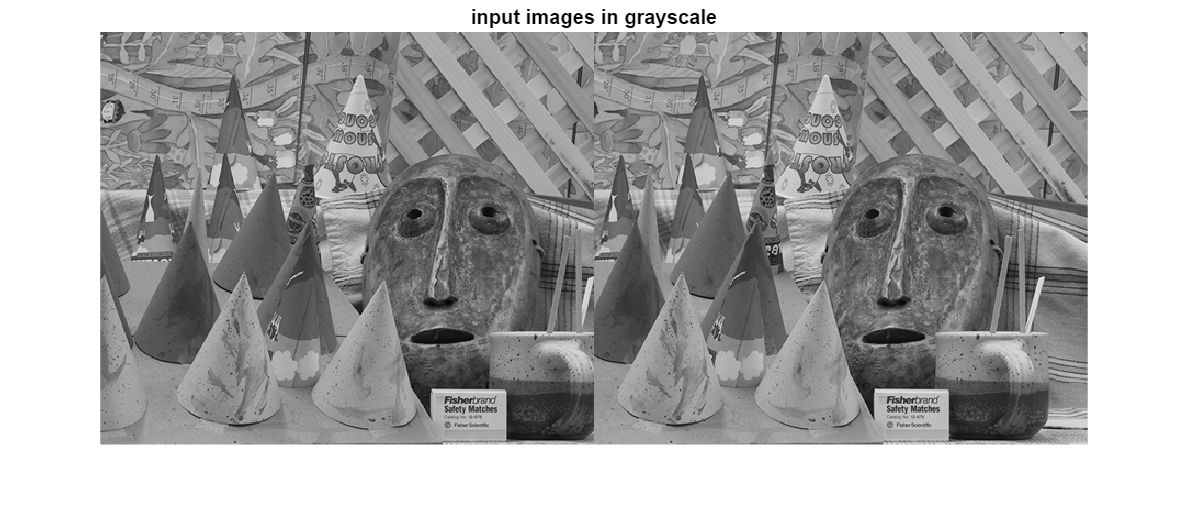

%  Read in two images and convert to grayscale
imgL = double(rgb2gray(imread("conesLeft.ppm")));
imgR = double(rgb2gray(imread("conesRight.ppm")));

imshow(cat( 2, uint8(imgL), uint8(imgR) )), title("input images in grayscale");

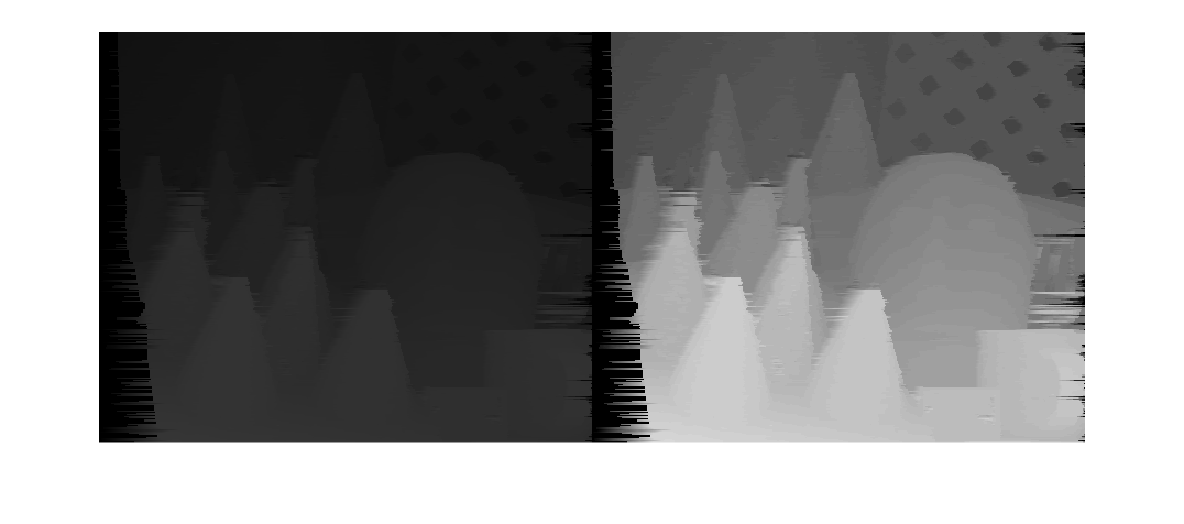

% Initialize some values
[nrows, ncols] = size(imgL);
Occlusion = 0.2;
Disparity  = NaN(nrows, ncols);

% 3x3 patches for each row
for irow = 2: nrows-1
    % Extract 3 rows from each image
    tmpL = imgL(irow-1:irow+1, :);
    tmpR = imgR(irow-1:irow+1, :);
    
    % Get all patches
    patchesL = im2col(tmpL, [3,3]);
    patchesR = im2col(tmpR, [3 3]);
    % disp(patchesL);

    % Normalize each patch of the two matrices
    normalized_patchesL = norm_patch(patchesL);
    normalized_patchesR = norm_patch(patchesR);

    % Obtain dsi
    ncc = transpose(normalized_patchesL) * normalized_patchesR;
    dsi = 1-ncc;
    % imshow(dsi);

    [r,c] = size(dsi);
    % p = r = length of right scanline
    % q = c = length of left scanline

    % Initialize cost matrix & path matrix
    Cost = NaN(r+1, c+1);
    M = NaN(r,c);

    % Initialize 1st column & 1st row of cost matrix, value start from 0
    for i = 1:r+1
        Cost(i, 1) = (i-1)*Occlusion;
    end
    for i = 1: c+1
        Cost(1, i) = (i-1)*Occlusion;
    end

    % Assign values to cost matrix & path matrix
    for i = 2: r+1
        for j = 2: c+1
            [ Cost(i, j), M(i-1, j-1) ] = min( ...
                [Cost(i-1, j-1)+dsi(i-1, j-1), ...
                Cost(i-1, j) + Occlusion, ...
                Cost(i, j-1) + Occlusion]);
        end
    end

    % disparityMap = NaN(r, c);
    currRow = r;      % p
    currCol = c;      % q

    % Initialize coordinates for the line
    % lineX = [];
    % lineY = [];

    % Loop from the bottom right corner to top right corner
    while currRow>0 && currCol>0
        % disparityMap(currRow, currCol) = M(currRow, currCol);
        Disparity(irow, currRow) = currRow-currCol;

        switch M(currRow, currCol)
            case 1
                currRow = currRow - 1; 
                currCol = currCol - 1;
            case 2
                currRow = currRow - 1;
            case 3
                currCol = currCol - 1;
        end

        % Store coordinates for the line
        % lineX = [lineX, currCol];
        % lineY = [lineY, currRow];
    end

    % % Display the disparity map of each row -- takes too much time
    % figure;
    % imshow(dsi);
    % hold on;
    % 
    % % Plot the line on the DSI
    % plot(lineX, lineY, 'r', 'LineWidth', 2);
    % title('Disparity Map with Path');
    % 
    % hold off;
end

% Find rows and columns with all NaN values
nanRows = all(isnan(Disparity), 2);
nanCols = all(isnan(Disparity), 1);

% Remove rows and columns with all NaN values
Disparity(nanRows, :) = [];
Disparity(:, nanCols) = [];

% show Disparity
imshow(cat( 2, uint8(Disparity), uint8(Disparity*4) ));

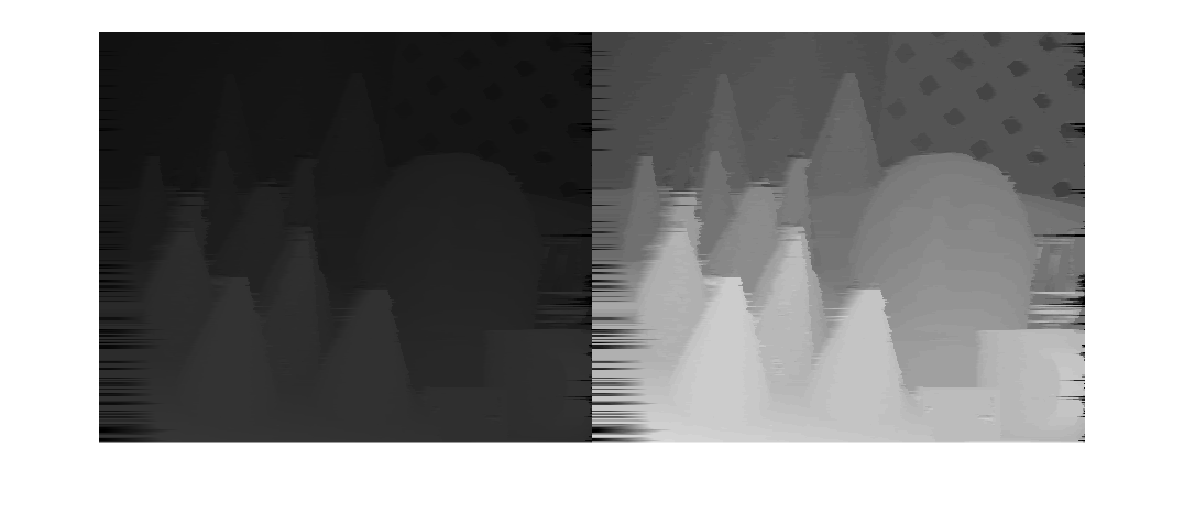

% Occlusion filling
for i = 1:size(Disparity, 1)
    for j = size(Disparity, 2)-1:-1:1  % Corrected loop condition
        if isnan(Disparity(i, j)) && ~isnan(Disparity(i, j+1))
            Disparity(i, j) = Disparity(i, j+1);
        end
    end
end

% show Disparity
imshow(cat( 2, uint8(Disparity), uint8(Disparity*4) ));

function normalized_patch = norm_patch(matrix)
    % Get column means & stds
    mean_values = mean(matrix);
    std_values = std(matrix);

    % Duplicate mean and std
    mean_matrix = repmat(mean_values, size(matrix, 1), 1);
    std_matrix = repmat(std_values, size(matrix, 1), 1);

    normalized_patch = (matrix - mean_matrix) ./ std_matrix;
end